# **Session 1: Working with an existing data pipeline with DataJoint**

This live scripts introduce how to work with an existing data pipeline, we will cover the following topics:

- Check schema structure and table definitions

- Flexible queries

- Fetching from query results

## Schema structure and table definitions

Schemas are groups of tables that are intuitively related. In the U19 pipeline, we have the following schemas:

- lab: the lab schema contains general information of the lab

- subject: the subject schema contains information about the animals

- action: the action schema contains water, weighing, and action item information

- acquisition: the acquisition schema contains behavioral information, and also the scanning information of the two-photon recording

- behavior: the behavior schema contains the processing steps of the behavioral experiments.

To check the schema structure, we could use `erd` to draw a diagram (entity relational diagram)

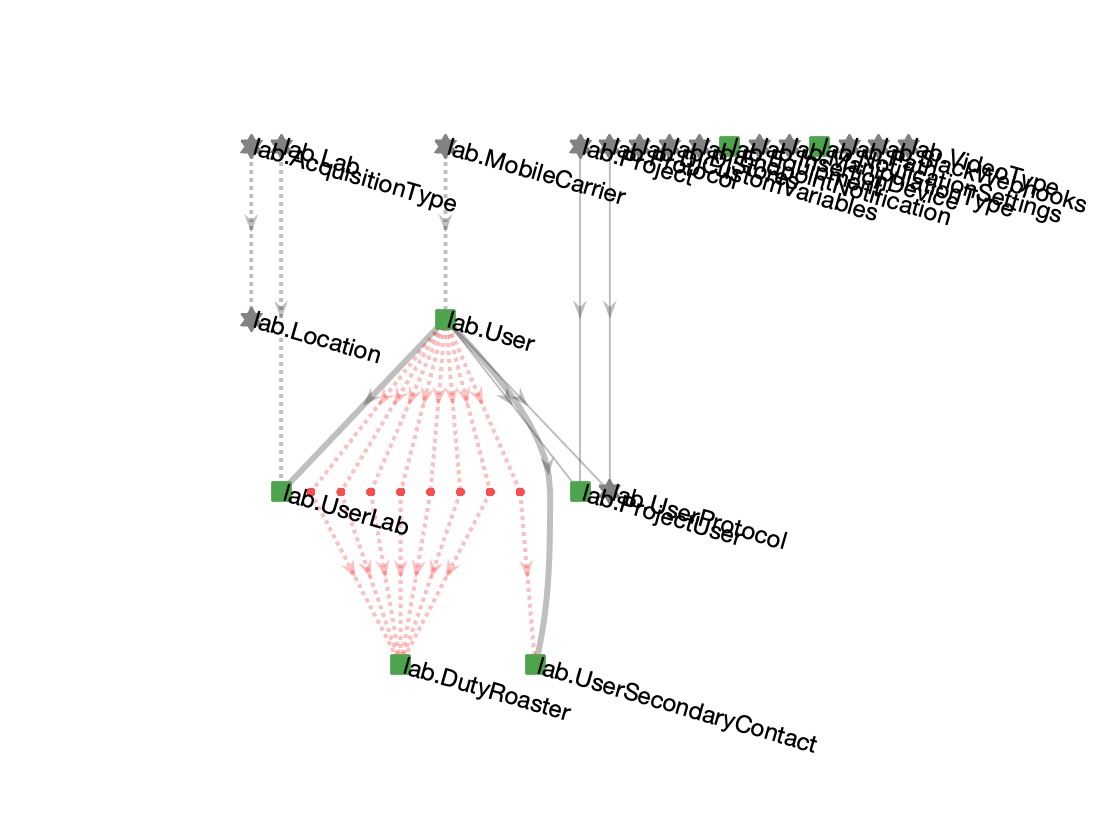

erd lab

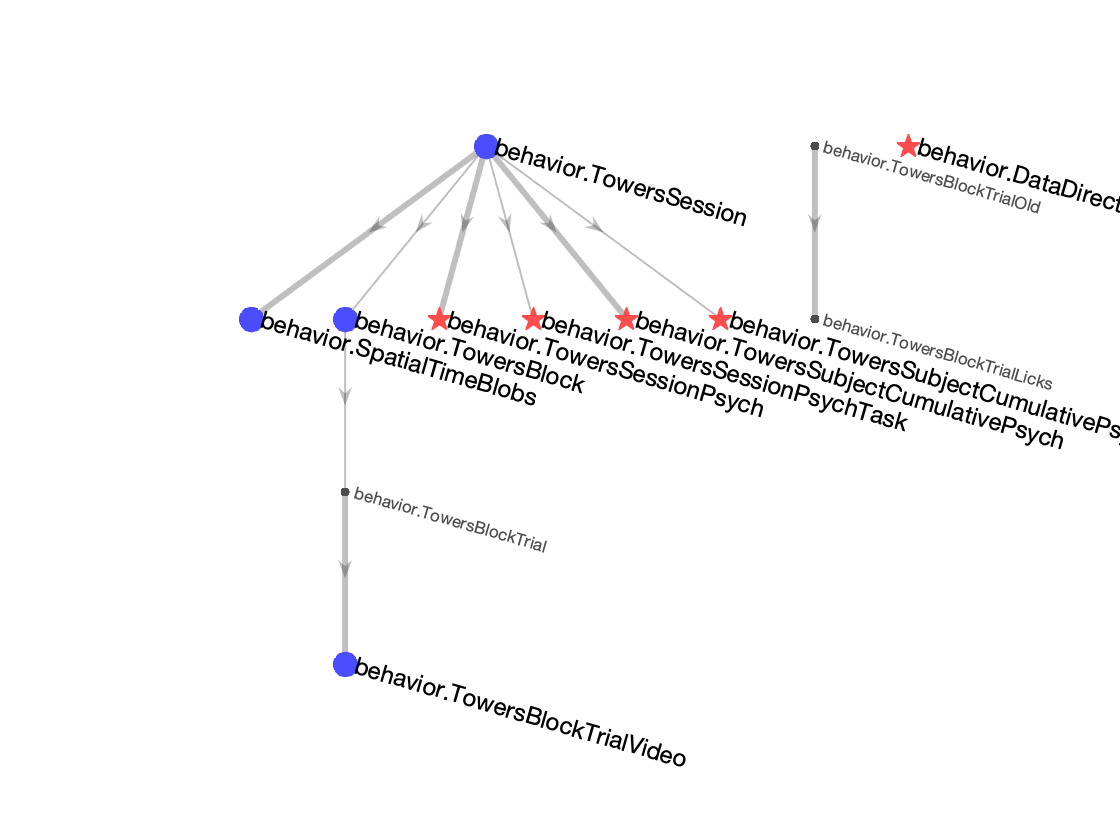

erd behavior

There are five types of tables:

- Manual tables (green squares): tables for manual information, such as Subject, lost if deleted

- Lookup tables (gray stars): tables for general information, such as some parameter settings

- Imported tables (blue dots): tables that are ingested from external files, such as recording tiff files from two-photon imaging, allowing auto-populate. When deleted, the entries were recoverable if the external files still exist.

- Computed tables (red stars): tables that are computed from tables within the database, allow auto-populate. Easily recoverable when the entries are deleted.

- Part tables (gray little dots): allow insertion by their master tables.

There are three types of table dependencies:

- One to one: child table and its parent table has the exact same primary key.

- One to many: other than the primary key of the parent table, the child table has some other fields as part of primary key

- Secondary attribute dependency: a secondary attribute is a field of the primary key of another table

- Many to many: implemented with two one-to-many dependencies

We could use `describe` to check a table definition. The --- separates the primary key and secondary attributes, -> indicates a dependency to its parent table. For example, the table subject.Subject has a one-to-many dependency with its parent table lab.User

describe(subject.Subject)

ans =     '%{
     # 
     subject_fullname            : varchar(64)                   # username_mouse_nickname
     ---
     subject_nickname            : varchar(16)                   # 
     user_id                     : varchar(32)                   # username
     genomics_id=null            : int                           # number from the facility
     sex="Unknown"               : enum('Male','Female','Unknown') # sex
     dob=null                    : date                          # birth date
     head_plate_mark=null        : blob                          # little drawing on the head plate for mouse identification
     location                    : varchar(32)                   # 
     protocol=null               : varchar(16)                   # protocol number
     line=null                   : varchar(128)                  # name
     subject_description         : varchar(255)                  # description
     initial_weight=null         : float                        

We could also directly print out a table to get an overview of the table contents, the primary key columns are CAPITALIZED

subject.Subject

ans = Object subject.Subject

 ::  ::

         SUBJECT_FULLNAME         subject_nickname       user_id       genomics_id       sex             dob            location      protocol           line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    __________________________    _________________    ____________    ___________    __________    ______________    ____________    ________    __________________    ___________________    ______________    ____________________    ____________

Another example, 

action.Weighing

ans = Object action.Weighing

 ::  ::

    SUBJECT_FULLNAME         WEIGHING_TIME         weigh_person        location         weight
    ________________    _______________________    ____________    _________________    ______

    {'ariordan_516'}    {'2020-02-28 16:09:00'}    {'ss31'    }    {'pni-174cr4jk2'}     32.8 
    {'ariordan_516'}    {'2020-02-29 13:46:00'}    {'baptista'}    {'pni-174cr4jk2'}     31.1 
    {'ariordan_516'}    {'2020-03-01 12:45:00'}    {'baptista'}    {'pni-174cr4jk2'}     30.4 
    {'ariordan_516'}    {'2020-03-02 13:04:00'}    {'baptista'}    {'pni-174cr4jk2'}     30.2 
    {'ariordan_516'}    {'2020-03-03 12:31:00'}    {'baptista'}    {'pni-174cr4jk2'}     29.3 
    {'ariordan_516'}    {'2020-03-04 16:36:00'}    {'ss31'    }    {'pni-174cr4jk2'}     28.7 
    {'ariordan_516'}    {'2020

## Flexible Queries

DataJoint supports powerful but intuitive queries. We will list a few important ones:

- Restriction (filter): & or -, filter the entries with some criteria.

- Join: *, gather fields together from different tables.

- proj(): only focus on a subset of secondary attribute, rename field and simple computation

- aggr(): simple computations on one against some other tables

### Restrictions (Filters)  & takes multiple forms

% restrictor as a string
subject.Subject & 'user_id = "lpinto"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id       sex             dob            location      protocol         line         subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    ________________    ________________    __________    ___________    __________    ______________    ____________    ________    ______________    ___________________    ______________    ____________________    _____________    ____________

% restrictor as a string, unequal
subject.Subject & 'dob > "2019-01-01"'

ans = Object subject.Subject

 ::  ::

         SUBJECT_FULLNAME         subject_nickname       user_id       genomics_id       sex             dob            location      protocol           line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    __________________________    _________________    ____________    ___________    __________    ______________    ____________    ________    __________________    ___________________    ______________    ____________________    ____________

% restrictor as a string, within a range
subject.Subject & 'dob between "2019-01-01" and "2019-02-01"'

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME     subject_nickname      user_id       genomics_id       sex             dob            location      protocol                line                 subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    _________________    ________________    ____________    ___________    __________    ______________    ____________    ________    _____________________________    ___________________    ______________    ____________________    __________

% restrictor as a string, "or" 
subject.Subject & 'sex in ("Male", "Female")'

ans = Object subject.Subject

 ::  ::

         SUBJECT_FULLNAME         subject_nickname       user_id       genomics_id       sex             dob            location      protocol           line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    __________________________    _________________    ____________    ___________    __________    ______________    ____________    ________    __________________    ___________________    ______________    ____________________    ____________

% restrictor as a string, "or" 
subject.Subject & 'sex = "Male" or sex = "Female"'

ans = Object subject.Subject

 ::  ::

         SUBJECT_FULLNAME         subject_nickname       user_id       genomics_id       sex             dob            location      protocol           line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    __________________________    _________________    ____________    ___________    __________    ______________    ____________    ________    __________________    ___________________    ______________    ____________________    ____________

For more syntax of restrictors as a string, check on MYSQL syntax. DataJoint supports most of the MYSQL syntax.

DataJoint also takes a struct as a restrictor:

subject.Subject & struct('user_id', 'lpinto', 'sex', 'Male')

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id      genomics_id      sex            dob            location      protocol          line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    ________________    ________________    __________    ___________    ________    ______________    ____________    ________    _________________    ___________________    ______________    ____________________    _____________    __________

Retrictor as a array of struct perform the 'or' logic.

subject.Subject & [struct('user_id', 'lpinto', 'sex', 'Male'), struct('user_id', 'hnieh', 'sex', 'Male')]

ans = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id     genomics_id      sex            dob            location      protocol       line        subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    ________________    ________________    _________    ___________    ________    ______________    ____________    ________    ___________    ___________________    ______________    ____________________    _____________    _______________

Restrict with other tables.

All mice that have a session

acquisition.Session & (subject.Subject & 'user_id="sbolkan"')

ans = Object acquisition.Session

 ::  ::

     SUBJECT_FULLNAME       SESSION_DATE     SESSION_NUMBER      session_start_time          session_end_time        session_location       task       level    set_id                                           stimulus_bank                                                          stimulus_commit                   session_performance    num_trials    session_narrative                                        session_protocol                                        is_bad_session    session_comments    num_trials_try    session_code_version
    ___________________    ______________    ______

All mice that don't have a session

subject.Subject - acquisition.Session

ans = Object subject.Subject

 ::  ::

          SUBJECT_FULLNAME             subject_nickname        user_id       genomics_id       sex             dob            location      protocol           line           subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    _____________________________    ____________________    ____________    ___________    __________    ______________    ____________    ________    __________________    ___________________    ______________    ____________________    

All forms of restrictors could be combined:

q = subject.Subject & [struct('user_id', 'koay', 'sex', 'Male'), struct('user_id', 'hneih', 'sex', 'Male')] & 'subject_nickname="K62"'

q = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname    user_id     genomics_id      sex          dob          location      protocol        line         subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    ________________    ________________    ________    ___________    ________    __________    ____________    ________    _____________    ___________________    ______________    ____________________    _____________    _______________

      

### Join `*` gathers fields from different tables together

subject.Subject * action.WaterAdministration

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    ADMINISTRATION_DATE    subject_nickname      user_id       genomics_id      sex            dob            location      protocol       line        subject_description    initial_weight    notification_enabled    need_reweight    earned    supplement    received    watertype_name    head_plate_mark
    ________________    ___________________    ________________    ____________    ___________    ________    ______________    ____________    ________    

### Projection `proj(`) only keeps a subset of the secondary attributes

No arguments:

% with no arguments it only keeps the primary key
subject.Subject().proj()

ans = Object dj.internal.GeneralRelvar

          SUBJECT_FULLNAME      
    ____________________________

    {'jounhong_CaMKIIa_tetO_23'}
    {'jounhong_CaMKIIa_tetO_24'}
    {'jounhong_CaMKIIa_tetO_25'}
    {'jounhong_CaMKIIa_tetO_40'}
    {'jounhong_CaMKIIa_tetO_45'}
    {'jounhong_CaMKIIa_tetO_47'}
    {'jounhong_CaMKIIa_tetO_51'}
    {'jounhong_CaMKIIa_tetO_55'}
    {'jounhong_CaMKIIa_tetO_57'}
    {'jounhong_CaMKIIa_tetO_59'}
    {'jounhong_CaMKIIa_tetO_60'}
    {'jounhong_CaMKIIa_tetO_63'}

          ...

769 tuples (0.0565 s)


It also works like this.

proj(subject.Subject)

ans = Object dj.internal.GeneralRelvar

          SUBJECT_FULLNAME      
    ____________________________

    {'jounhong_CaMKIIa_tetO_23'}
    {'jounhong_CaMKIIa_tetO_24'}
    {'jounhong_CaMKIIa_tetO_25'}
    {'jounhong_CaMKIIa_tetO_40'}
    {'jounhong_CaMKIIa_tetO_45'}
    {'jounhong_CaMKIIa_tetO_47'}
    {'jounhong_CaMKIIa_tetO_51'}
    {'jounhong_CaMKIIa_tetO_55'}
    {'jounhong_CaMKIIa_tetO_57'}
    {'jounhong_CaMKIIa_tetO_59'}
    {'jounhong_CaMKIIa_tetO_60'}
    {'jounhong_CaMKIIa_tetO_63'}

          ...

769 tuples (0.0308 s)


Actually this is more commonly used because adding filters to this is easy.

proj(subject.Subject & 'user_id="lpinto"')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME
    ________________

    {'lpinto_ai10'} 
    {'lpinto_ai11'} 
    {'lpinto_ai12'} 
    {'lpinto_ai13'} 
    {'lpinto_ai7' } 
    {'lpinto_ai8' } 
    {'lpinto_ai9' } 
    {'lpinto_GP1' } 
    {'lpinto_GP2' } 
    {'lpinto_GP3' } 
    {'lpinto_GP4' } 
    {'lpinto_GP5' } 

          ...

74 tuples (0.0407 s)


Now keep some other attributes as well:

proj(subject.Subject, 'dob', 'sex')

ans = Object dj.internal.GeneralRelvar

         SUBJECT_FULLNAME            sex             dob      
    __________________________    __________    ______________

    {'ariordan_516'          }    {'Male'  }    {'2019-09-28'}
    {'ariordan_528'          }    {'Male'  }    {'2019-11-04'}
    {'ariordan_529'          }    {'Male'  }    {'2019-11-04'}
    {'efonseca_EF002'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_EF003'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_EF004'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_ef150_actp004'}    {'Male'  }    {'2021-05-10'}
    {'efonseca_ef158_actp005'}    {'Female'}    {'2021-05-12'}
    {'efonseca_ef164'        }    {'Female'}    {'2021-05-12'}
    {'efonseca_ef164_actp006'}    {'Female'}    {'2021-05-12'}
    {'efonseca_ef165'        }    {'Female'}    {'2021-05-12'}
    {'efonseca_ef165_actp007'}    {'Fe

`proj()` also allows renaming the fields

proj(subject.Subject, 'dob->birth_date', 'sex')

ans = Object dj.internal.GeneralRelvar

         SUBJECT_FULLNAME            sex          birth_date  
    __________________________    __________    ______________

    {'ariordan_516'          }    {'Male'  }    {'2019-09-28'}
    {'ariordan_528'          }    {'Male'  }    {'2019-11-04'}
    {'ariordan_529'          }    {'Male'  }    {'2019-11-04'}
    {'efonseca_EF002'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_EF003'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_EF004'        }    {'Male'  }    {'2019-12-20'}
    {'efonseca_ef150_actp004'}    {'Male'  }    {'2021-05-10'}
    {'efonseca_ef158_actp005'}    {'Female'}    {'2021-05-12'}
    {'efonseca_ef164'        }    {'Female'}    {'2021-05-12'}
    {'efonseca_ef164_actp006'}    {'Female'}    {'2021-05-12'}
    {'efonseca_ef165'        }    {'Female'}    {'2021-05-12'}
    {'efonseca_ef165_actp007'}    {'Fe

and some simple computations:

Example 1: get the date of a weighing

proj(action.Weighing & 'subject_fullname="hnieh_E39"', 'date(weighing_time)->weighing_date')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME         WEIGHING_TIME         weighing_date 
    ________________    _______________________    ______________

     {'hnieh_E39'}      {'2017-08-02 16:24:00'}    {'2017-08-02'}
     {'hnieh_E39'}      {'2017-08-03 15:48:00'}    {'2017-08-03'}
     {'hnieh_E39'}      {'2017-08-04 16:21:00'}    {'2017-08-04'}
     {'hnieh_E39'}      {'2017-08-07 18:05:00'}    {'2017-08-07'}
     {'hnieh_E39'}      {'2017-08-08 16:34:00'}    {'2017-08-08'}
     {'hnieh_E39'}      {'2017-08-09 17:21:00'}    {'2017-08-09'}
     {'hnieh_E39'}      {'2017-08-10 17:06:00'}    {'2017-08-10'}
     {'hnieh_E39'}      {'2017-08-11 15:59:00'}    {'2017-08-11'}
     {'hnieh_E39'}      {'2017-08-12 16:13:00'}    {'2017-08-12'}
     {'hnieh_E39'}      {'2017-08-14 17:50:00'}    {'2017-08-14'}
     {'hnieh_E39'}      {'2017-08-15 18:54:00'}    {'2017-08-15'}

Example 2: What is the age of an animal when performing each session?

% First get the date of birth and the session date into the same query
q = subject.Subject().proj('dob') * acquisition.Session().proj() & 'dob != ""'

q = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    SESSION_DATE    SESSION_NUMBER        dob     
    ________________    ____________    ______________    ____________

      'hnieh_E58'       '2017-10-17'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-18'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-19'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-20'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-23'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-24'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-25'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-26'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-27'          0           '2016-11-14'
      'hnieh_E58'       '2017-10-31'        

% Then perform the computation with proj()
q.proj('datediff(session_date, dob)->age_in_days')

ans = Object dj.internal.GeneralRelvar

    SUBJECT_FULLNAME    SESSION_DATE    SESSION_NUMBER    age_in_days
    ________________    ____________    ______________    ___________

      'hnieh_E58'       '2017-10-17'          0               337    
      'hnieh_E58'       '2017-10-18'          0               338    
      'hnieh_E58'       '2017-10-19'          0               339    
      'hnieh_E58'       '2017-10-20'          0               340    
      'hnieh_E58'       '2017-10-23'          0               343    
      'hnieh_E58'       '2017-10-24'          0               344    
      'hnieh_E58'       '2017-10-25'          0               345    
      'hnieh_E58'       '2017-10-26'          0               346    
      'hnieh_E58'       '2017-10-27'          0               347    
      'hnieh_E58'       '2017-10-31'          0      

 Aggregation `.aggr()`: simple computation of one table against another table

Example: how many animals does each user have?

lab.User().aggr(subject.Subject, 'count("subject_fullname")->n_animals')

ans = Object dj.internal.GeneralRelvar

     USER_ID      n_animals
    __________    _________

    'baptista'        1    
    'emanuele'        7    
    'hnieh'          50    
    'joelcf'          1    
    'jteran'          1    
    'koay'           19    
    'lpinto'         74    
    'lteachen'        1    
    'mioffe'         21    
    'sbolkan'         1    
    'ss31'            1    
    'testuser'       17    

          ...

13 tuples (0.121 s)


aggr(lab.User, subject.Subject, 'count("subject_fullname")->n_animals')

ans = Object dj.internal.GeneralRelvar

     USER_ID      n_animals
    __________    _________

    'baptista'        1    
    'emanuele'        7    
    'hnieh'          50    
    'joelcf'          1    
    'jteran'          1    
    'koay'           19    
    'lpinto'         74    
    'lteachen'        1    
    'mioffe'         21    
    'sbolkan'         1    
    'ss31'            1    
    'testuser'       17    

          ...

13 tuples (0.111 s)


## Fetching data

So far, we have been querying from the database, but did not get any data fetched, in the form of matlab data types. We could fetch from **any query** we performed so far. With the syntax `fetch(query, ...)` or `query.fetch(...)`

Fetch everything from a table: get an structure array of primary keys

subject.Subject().fetch()

ans = 769×1 struct array with fields:
    subject_fullname


fetch(subject.Subject)

ans = 191×1 struct array with fields:
    subject_fullname


Fetch a subset of fields, but still as an array of struct

subjects_stats = fetch(subject.Subject, 'sex', 'dob')

subjects_stats = 191×1 struct array with fields:
    subject_fullname
    sex
    dob


Everything you get with `fetch()` is an array of sturct, with the primary keys, even if you only have one entry. If you want other data formats to return without the primary key, here are two other options:

- fetch1(): works on queries only with one entry

- fetchn(): works on any queries

fetch1(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

ans = 22

fetchn(subject.Subject & 'subject_nickname="E70"', 'initial_weight')

ans = 22

fetch1(subject.Subject & 'subject_nickname="E70"', 'dob')

ans = '2017-11-20'

Fetch multiple fields at the same time, individually

[dob, sex, initial_weight] = fetch1(subject.Subject & 'subject_nickname="E74"', 'dob', 'sex', 'initial_weight')

dob = '2017-12-13'

sex = 'Male'

initial_weight = 30

subj = subject.Subject & 'subject_nickname="E74"'

subj = Object subject.Subject

 ::  ::

    SUBJECT_FULLNAME    subject_nickname     user_id     genomics_id      sex            dob            location      protocol         line         subject_description    initial_weight    notification_enabled    need_reweight    head_plate_mark
    ________________    ________________    _________    ___________    ________    ______________    ____________    ________    ______________    ___________________    ______________    ____________________    _____________    _______________</

subj_key = subj.fetch()

subj_key = struct with fields:
    subject_fullname: 'hnieh_E74'


[water_date, earned_water] = fetchn(action.WaterAdministration & subj_key, 'administration_date', 'earned');

Earned water as a function of date.

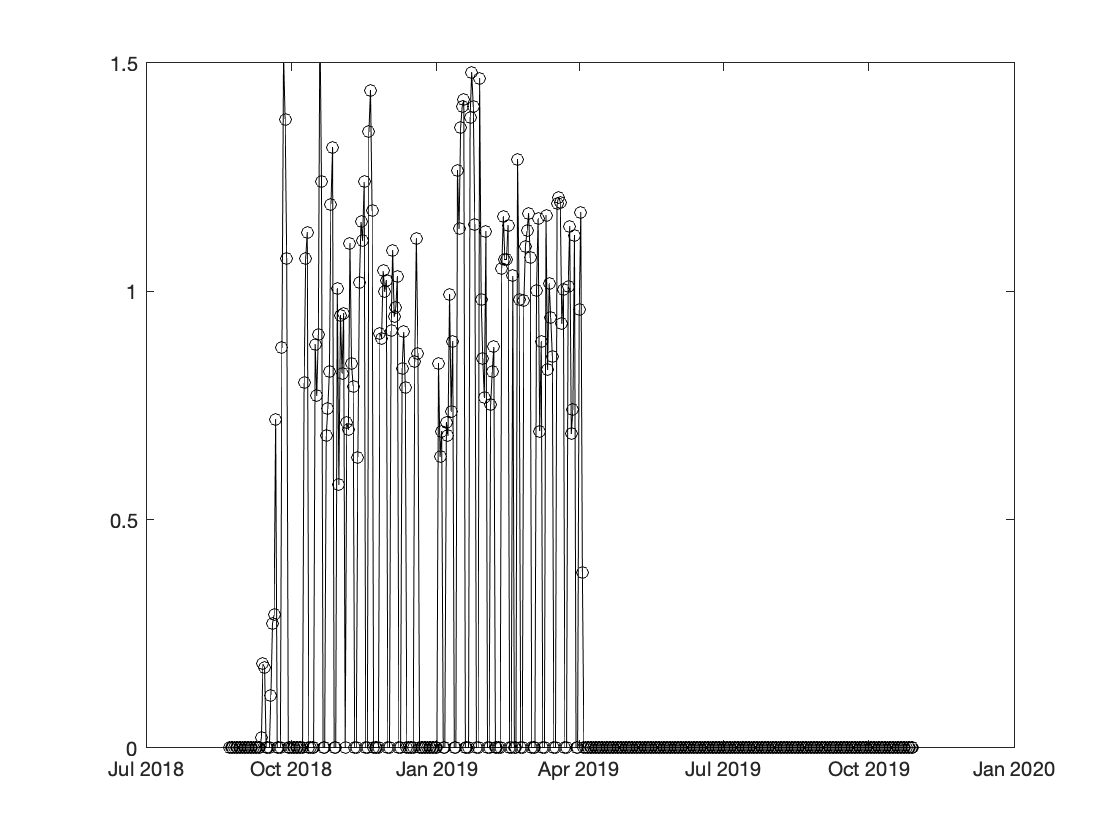

water_date = datetime(water_date);
figure; plot(water_date, earned_water, 'ko-')
ylim([0, 1.5])

Weight as a function of date.

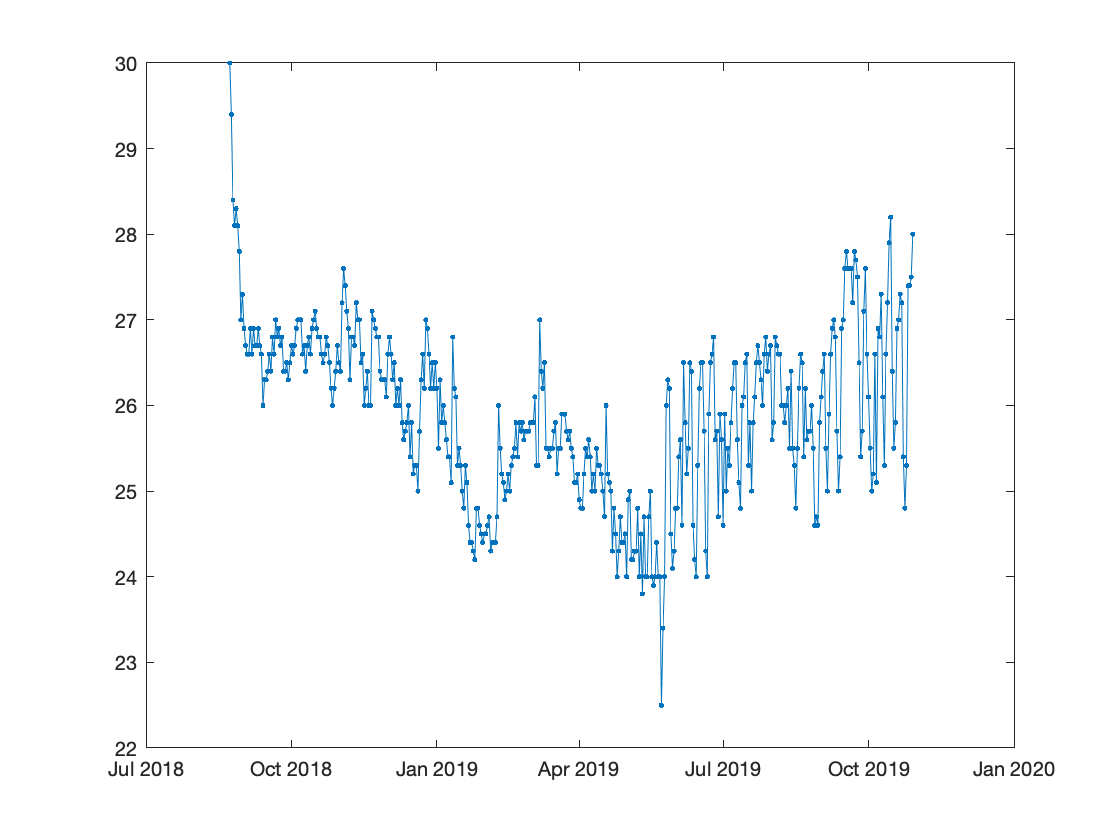

[weight_data] = fetch(...
    action.Weighing & subj_key, 'DATE(weighing_time)->weighing_date', 'weight');
weight = [weight_data.weight];
weighing_date = {weight_data.weighing_date};
weighing_date = datetime(weighing_date);
figure; plot(weighing_date, weight, '.-')

Plot both together:

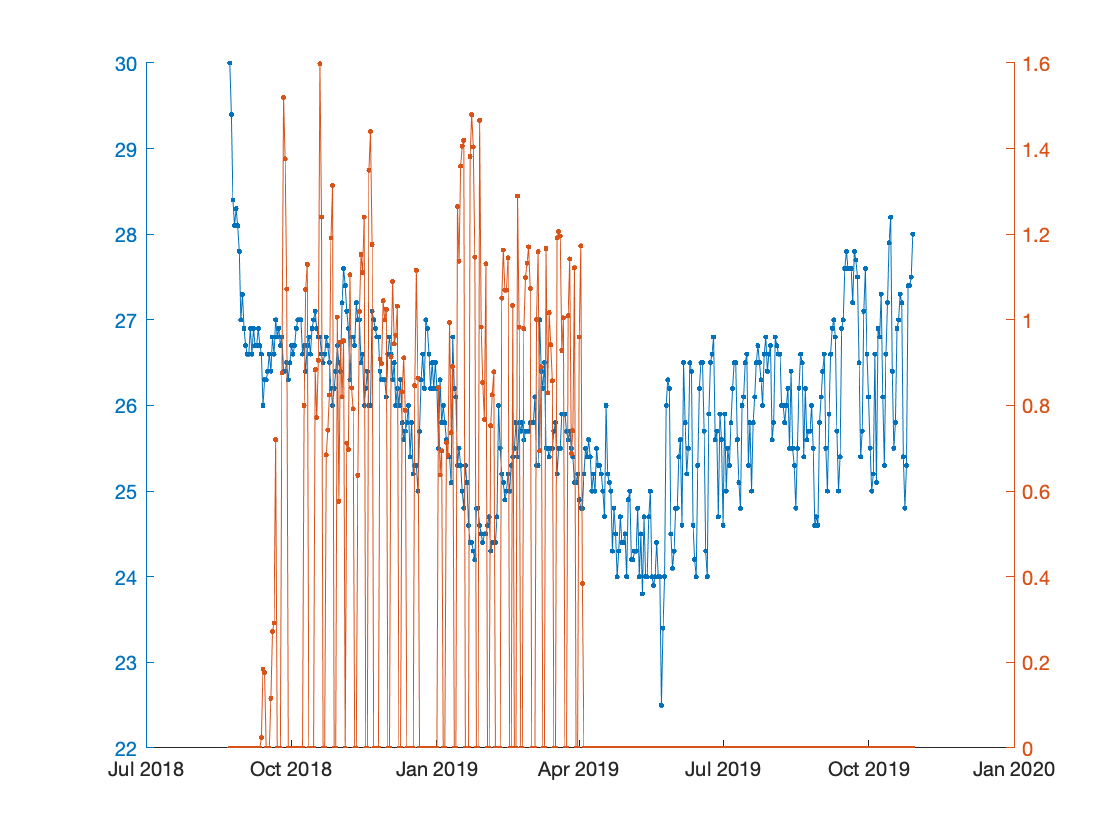

figure; hold on
yyaxis left
plot(weighing_date, weight, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Performance as a function of date

acquisition.Session

ans = Object acquisition.Session

 ::  ::

    SUBJECT_FULLNAME    SESSION_DATE    SESSION_NUMBER     session_start_time        session_end_time       session_location      task      level    set_id    stimulus_bank    stimulus_commit    session_performance    session_narrative                                        session_protocol                                         session_code_version
    ________________    ____________    ______________    _____________________    _____________________    ________________    ________    _____    ______    _____________    

acquisition.Session & subj_key

Plot performance as a function of date.

[session_date, performance] = fetchn(acquisition.Session & subj_key, 'session_date', 'session_performance');
session_date = datetime(session_date);
figure; plot(session_date, performance, '.-')

Plot both performance and earned water as a function of date.

figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

Compute trial numbers of a given date.

behavior.TowersBlockTrial & subj & 'session_date="2018-09-20"'

Compute trial numbers of each date

query = acquisition.Session & subj_key
[session_date, n_trials] = fetchn(query.aggr(behavior.TowersBlockTrial, 'count(*) -> n'), 'session_date', 'n');
session_date = datetime(session_date);
figure; hold on
yyaxis left
plot(session_date, performance, '.-')
yyaxis right
plot(water_date, earned_water, '.-')

## Summary

In session 1, we have covered basic methods to explore, browse and fetch data from the data pipeline. In the next session, we will learn how to generate different kinds of tables, ingest, delete, and compute entries.